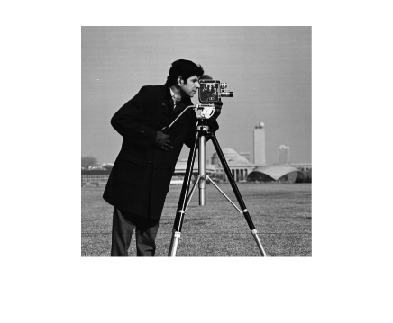

a=imread('cameraman.tif');
imshow(a)

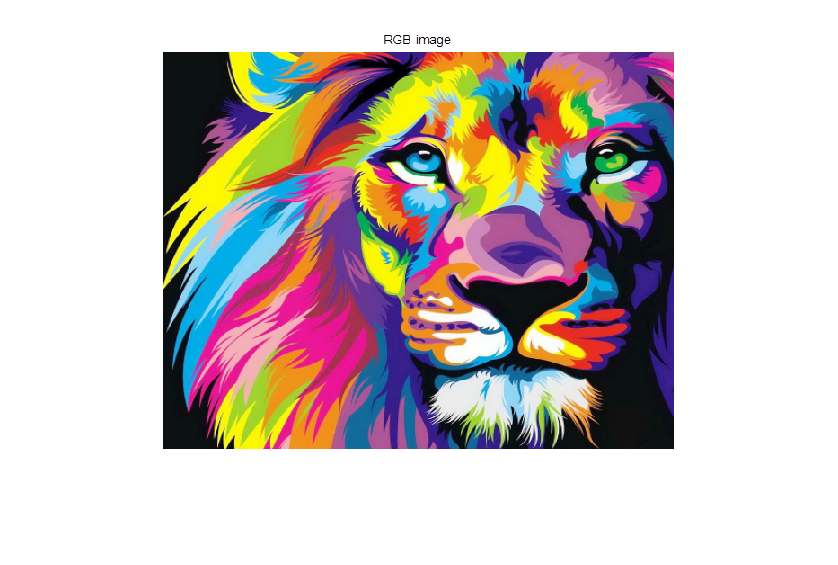


img=imread('rgb.png');
imshow(img)


[img3,b]=uigetfile('*.*','file select');
img=imread([b,img3]);
imshow(img)

j = imread('rgb.png');
imshow(j);

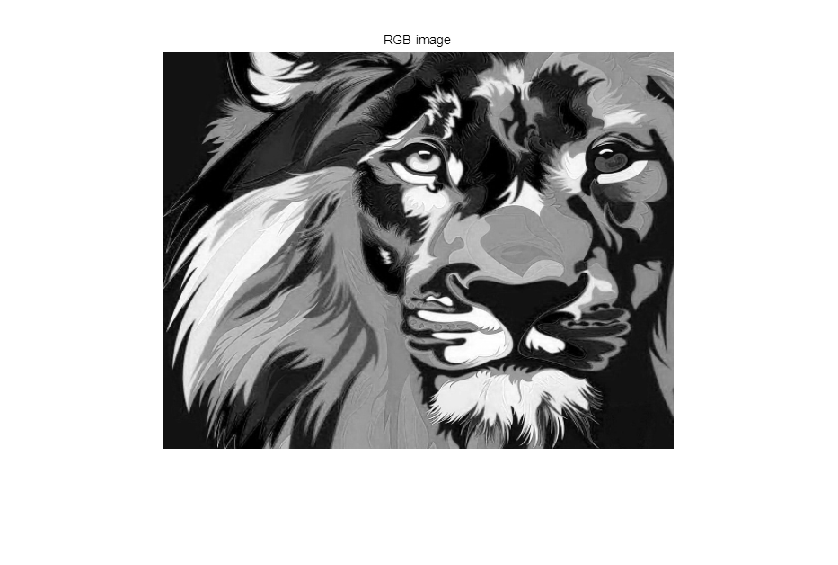

a = size(j);
b = j(:,:,3);
imshow(b);

Amax = max(b,[],"all");
Amin = min(b,[],"all");

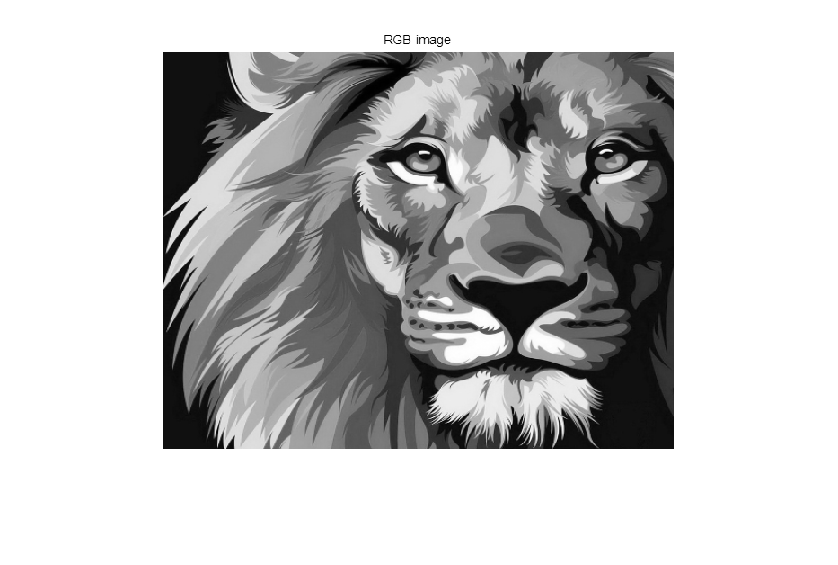

l = im2gray(img);
imshow(l);

k=size(l)

k =    525   751


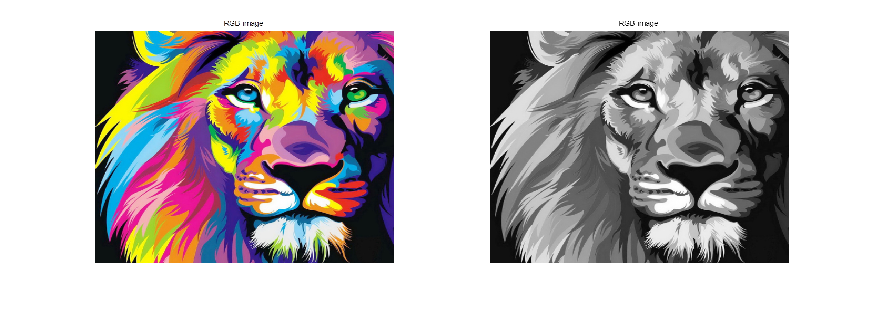

imshowpair(j,l,"montage");

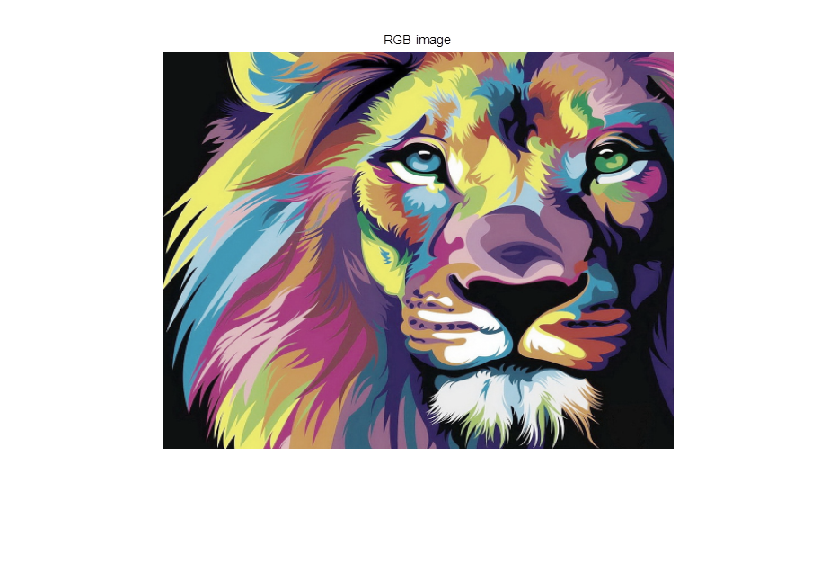

imshowpair(j,l,"blend");

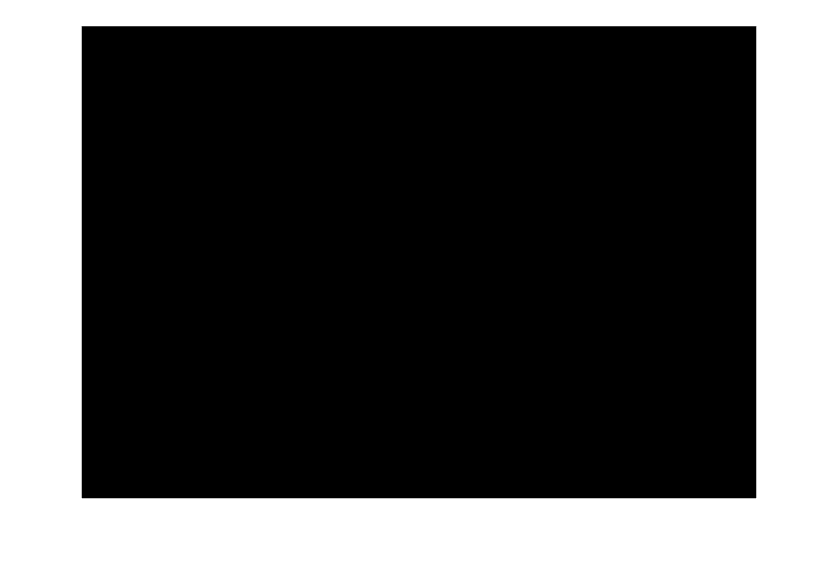

imshowpair(j,l,"diff");

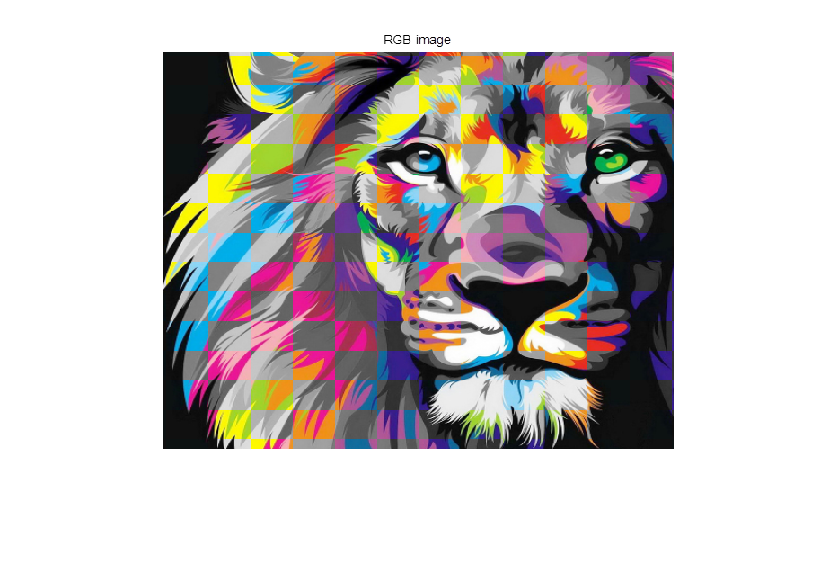

imshowpair(j,l,"checkerboard");

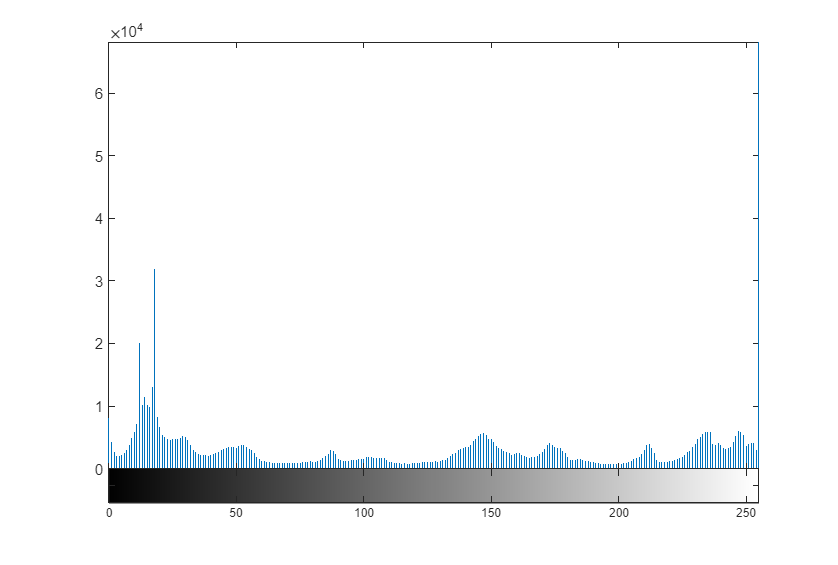

imhist(img)

Adj = imadjust(l)

Adj = 525×751 uint8 matrix
   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   255   255   255   2

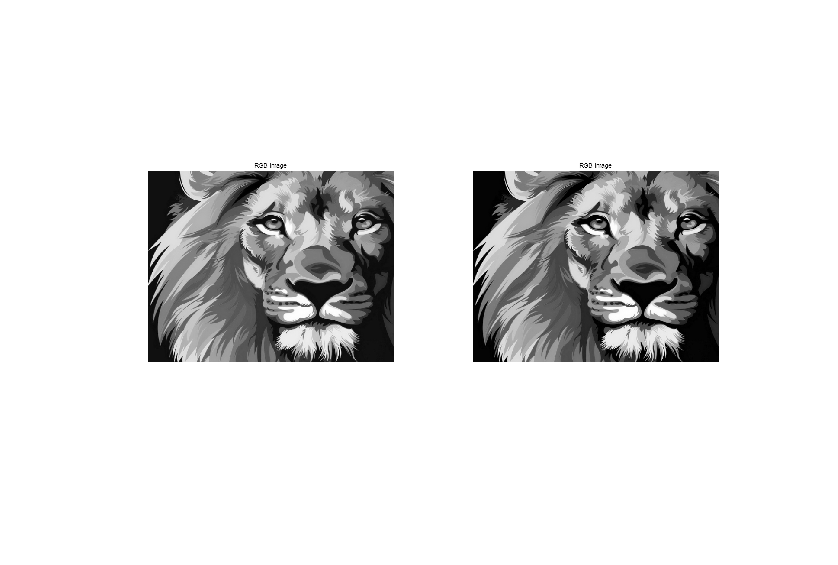

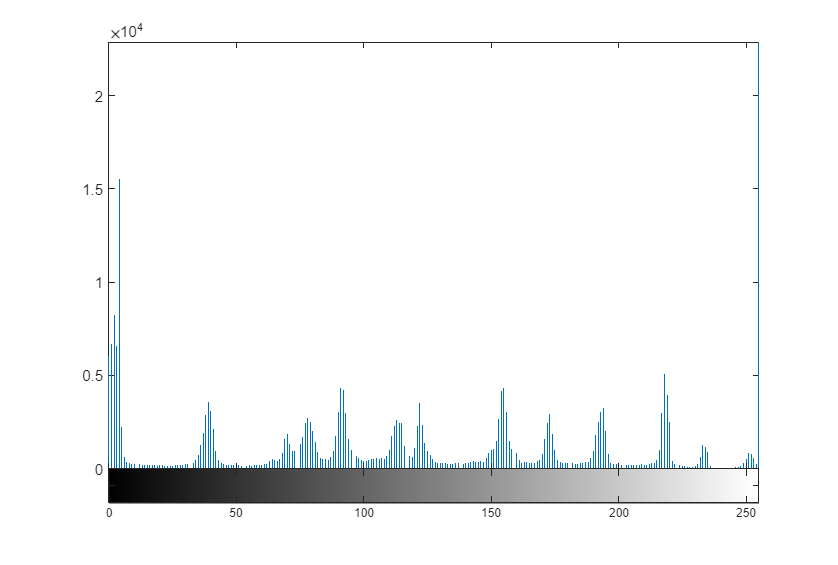

imshowpair(l,Adj,"montage");

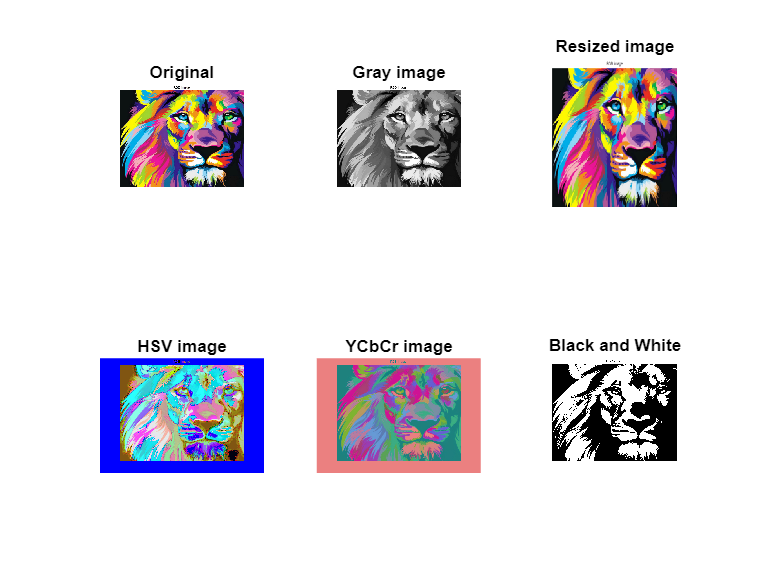

img1=imread('rgb.png');
b=rgb2gray(img1);
c=imresize(img1,[256 256]);
d=rgb2hsv(img1);
e=rgb2ycbcr(img1);
f=im2bw(img1);

subplot(2,3,1);imshow(img1); title('Original')
subplot(2,3,2);imshow(b); title('Gray image')
subplot(2,3,3);imshow(c); title('Resized image')
subplot(2,3,4);imshow(d); title('HSV image')
subplot(2,3,5);imshow(e); title('YCbCr image')
subplot(2,3,6);imshow(f); title('Black and White')

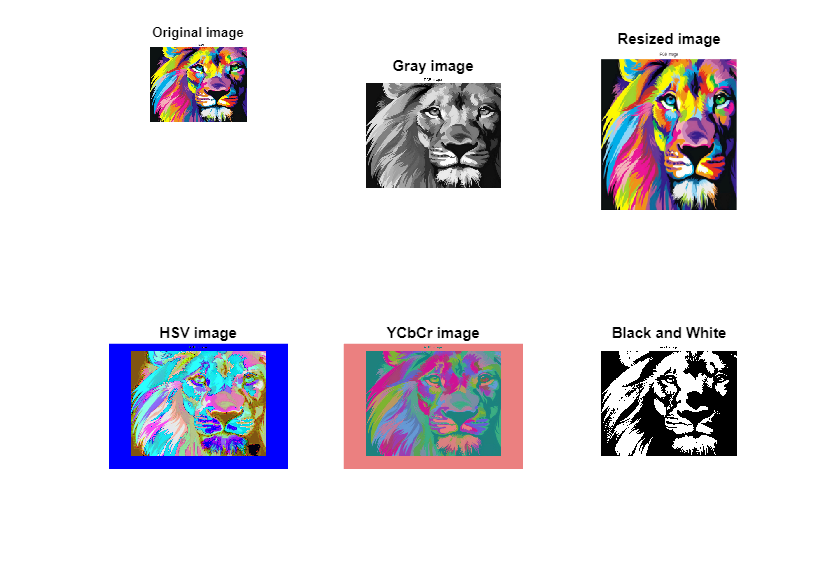

[a,b]=uigetfile('*.*','select an image');
c=imread([b a]);
subplot(4,3,1);
imshow(c);
title('Original image');

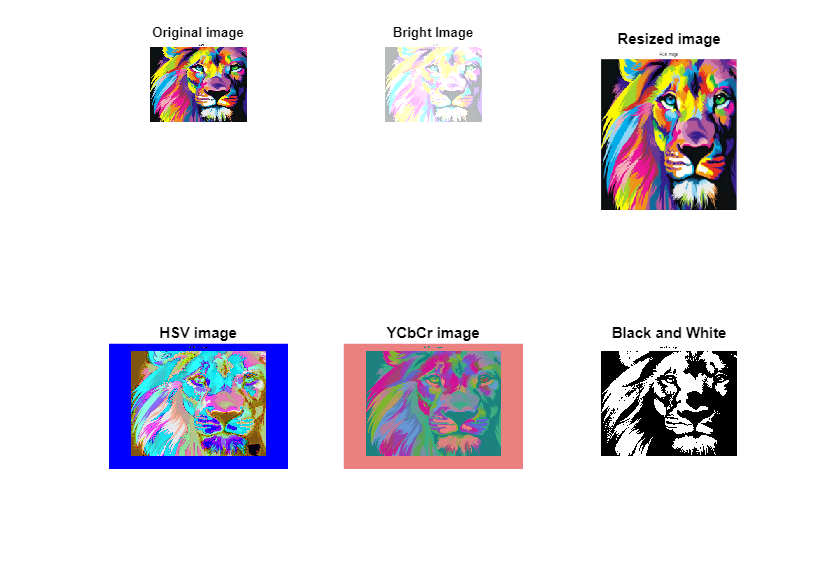

bright=c+170;
subplot(4,3,2); imshow(bright); title('Bright Image');

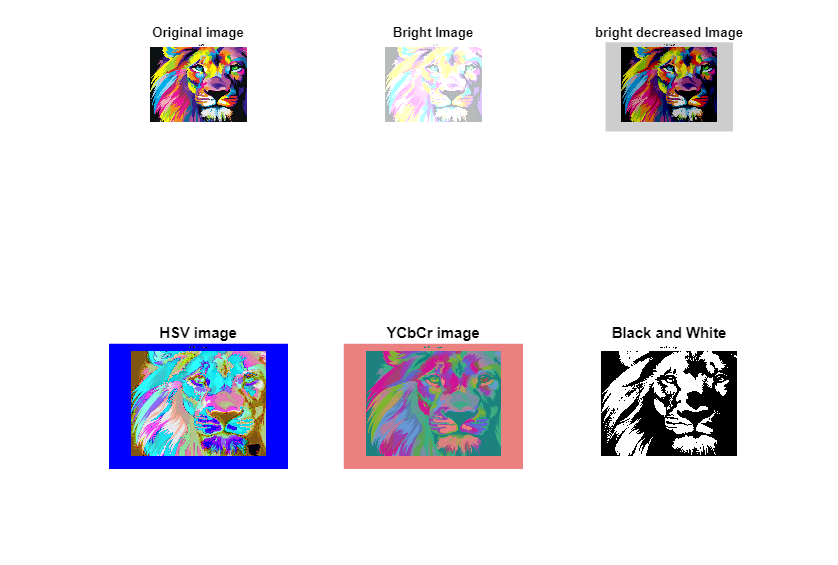

bright_suppressed=c-50;
subplot(4,3,3); imshow(bright_suppressed); title('bright decreased Image');

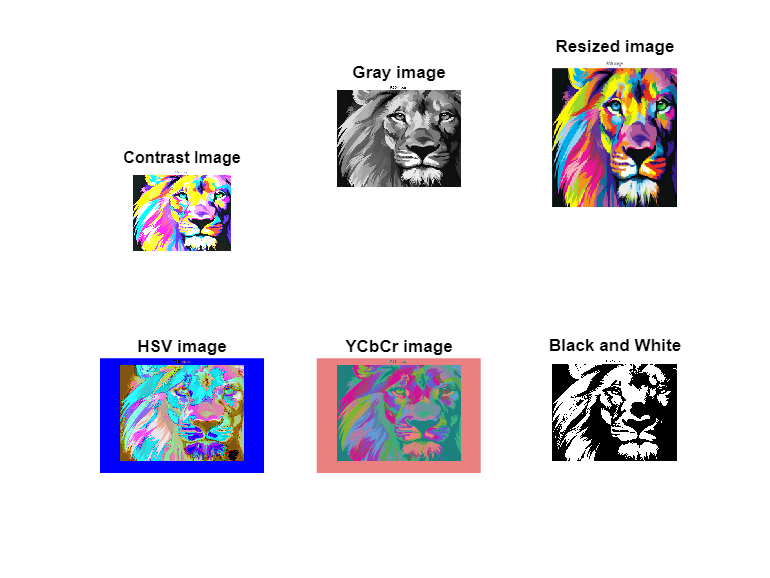

con=a.*2;
subplot(4,3,4); imshow(con); title('Contrast Image');